# Regelungsmathematische Methoden

## Abtastsystem eines linearen Systemmodells

Für Zustandsvektor $x={\left(x_1 ,x_2 \right)}^T$ und Eingang $u=u\left(t\right)$ sei das zeitkontinuierliche System


$$\begin{array}{l}
\dot{x} =\left\lbrack \begin{array}{cc}
-1 & 0\\
1 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack u,\;\;\;x\left(0\right)=x_0 \\
y=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack x
\end{array}$$


gegeben.

% system model
A = [-1 0; 1 0];
B = [1;0];
C = [0 1];
D = 0;
h = 0.1; % time step in seconds
time = 10; % simulation time in seconds

Definiere $u_1 \left(t\right)=\sin \left(t\right)$ und $u_2 \left(t\right)=0$ als Eingänge, sowie Anfangswerte $x_0$.

[u1,t] = gensig('sin', 2*pi, time , h);
u2 = zeros(size(t));
x0 = [0.1; 0.1];
sys = ss(A,B,C,D); % construct system model automatically

test_idx = int16(0.4*time/h) 

test_idx = int16
40

% t should never change...

## Task 1

Simulation mit lsim:

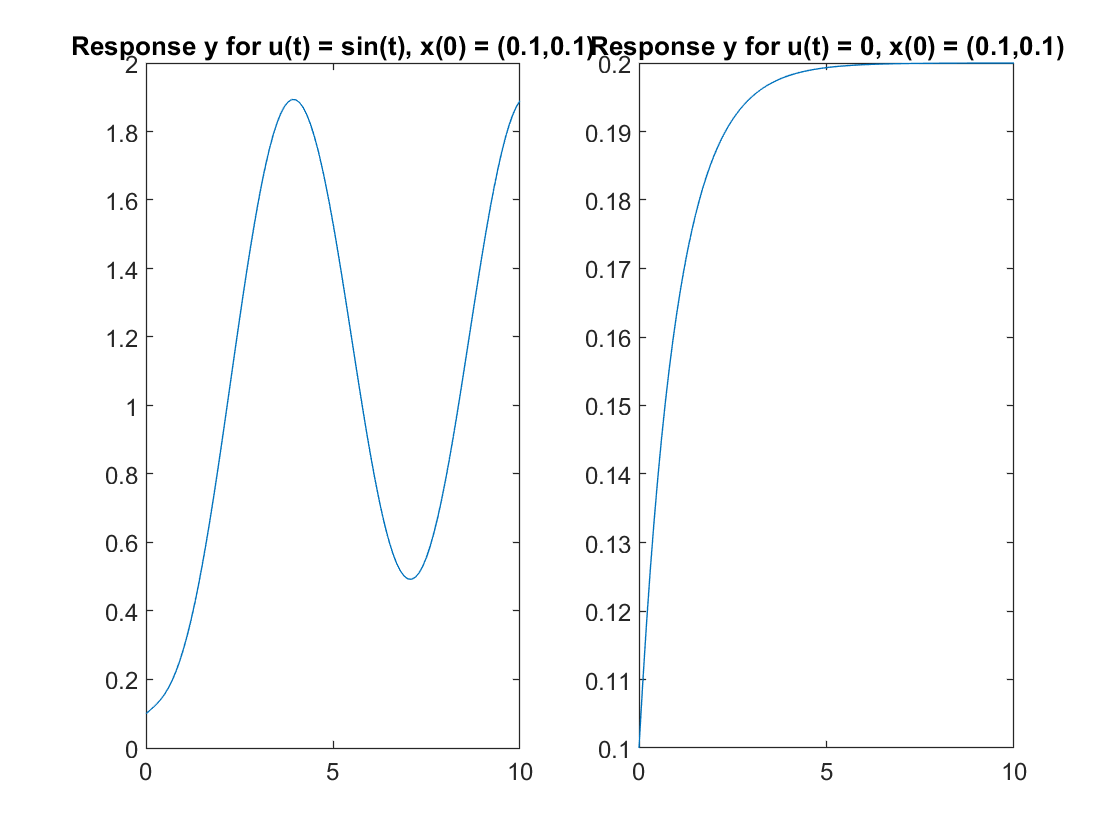

figure(1);

subplot(1,2,1);
[y_lsim_sin,~,~] = lsim(sys, u1, t, x0); % simulation of response
plot(t,y_lsim_sin);
title('Response y for u(t) = sin(t), x(0) = (' + strjoin(string(x0),',')+')')

subplot(1,2,2);
[y_lsim_0,~,~] = lsim(sys, u2, t, x0); % simulation of response
plot(t,y_lsim_0);
title('Response y for u(t) = 0, x(0) = (' + strjoin(string(x0),',')+')')

### Task 2

Simulation über explizites Euler-Verfahren:

Dazu ist die Iteration 


$$\begin{array}{l}
x_k =x\left(k\;h\right)=x_{k-1} +h\;f\left(t_{k-1} ,x_{k-1} \right)=\cdots \\
\;\;\;\;=x_{k-1} +h\;\left\lbrack \begin{array}{c}
x_{k-1}^1 +u_k \\
x_{k-1}^1 
\end{array}\right\rbrack 
\end{array}$$


zu implementieren. **Rechenweg abfotografieren!**

(Siehe Funktionen unten!)

figure(2);

subplot(1,2,1)
[t,y_eulerf_sin] = forward_euler(h, time, x0,u1);
y_lsim_sin = y_lsim_sin';
plot(t,y_eulerf_sin ,t,y_lsim_sin);
title('Explicit euler vs. lsim, u(t) = sin(t)');
fehler_eelsim_sin = max(abs(y_lsim_sin-y_eulerf_sin)) % max. fehler expl. euler

fehler_eelsim_sin = 0.0576

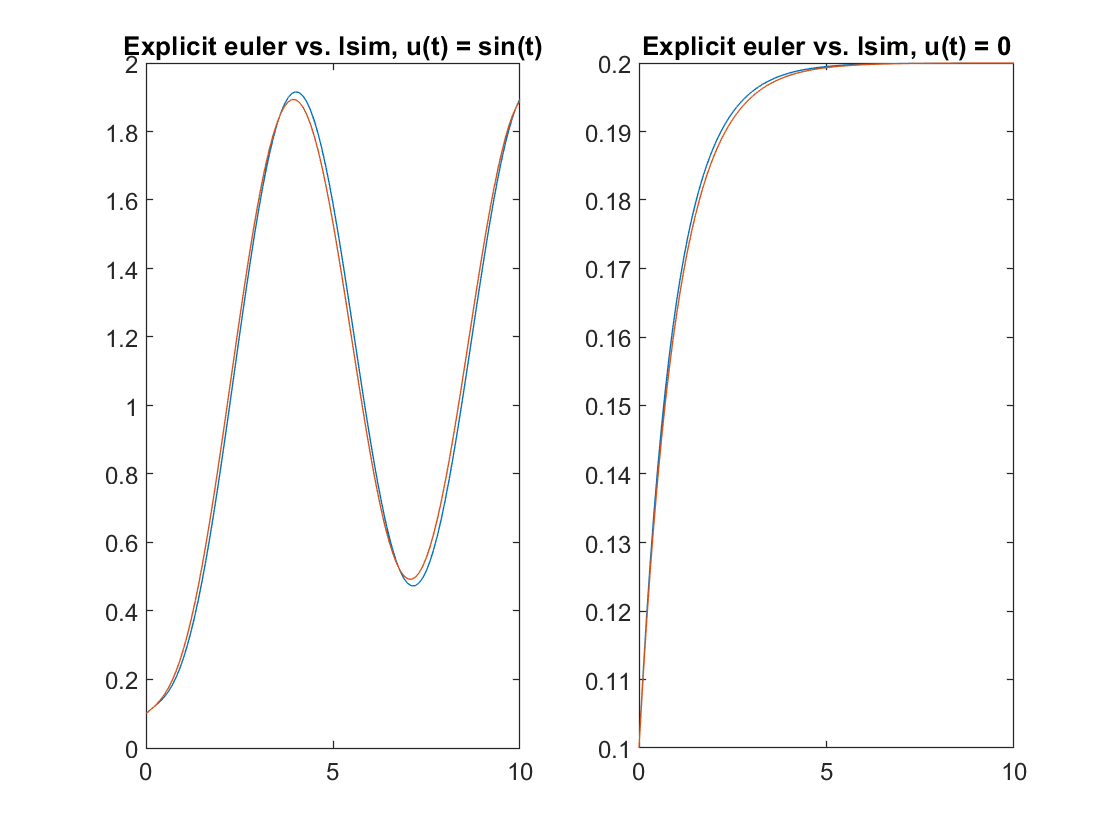


subplot(1,2,2)
[t,y_eulerf_0] = forward_euler(h, time, x0,u2);
y_lsim_0 = y_lsim_0';
plot(t,y_eulerf_0,t,y_lsim_0);
title('Explicit euler vs. lsim, u(t) = 0');

fehler_eelsim_0 = max(abs(y_lsim_0-y_eulerf_0))

fehler_eelsim_0 = 0.0019

### Task 3

Für das implizite Euler-Verfahren wird für die Approximation der Ableitung statt der (k-1)-ten Stützstelle die k-te verwendet, also gilt es die folgende Iteration zu lösen:


$$x_k =x_{k-1} +h\;f\left(t_k ,x_k \right)$$


Für diese implizite Iteration (Terme $x_k$ auf beiden Seiten), kann $x_k$ analytisch ausgedrückt werden:


$$x_k =\left\lbrack \begin{array}{c}
\frac{\left(x_{k-1}^1 +h*u_k \right)}{1+h}\\
x_{k-1}^2 +h*\frac{\left(x_{k-1}^1 +h*u_k \right)}{1+h}
\end{array}\right\rbrack$$


Diese Iteration ist in der Funktion "backwards_euler" implementiert.

figure(3);

subplot(1,2,1);
[t,y_eulerb_sin] = backward_euler(h, time, x0,u1);

plot(t,y_eulerb_sin,t,y_lsim_sin);
title('Implicit euler vs. lsim, u(t) = sin(t)')
fehler_eilsim_sin = max(abs(y_eulerb_sin-y_lsim_sin)) % max. fehler impl. euler

fehler_eilsim_sin = 0.0556

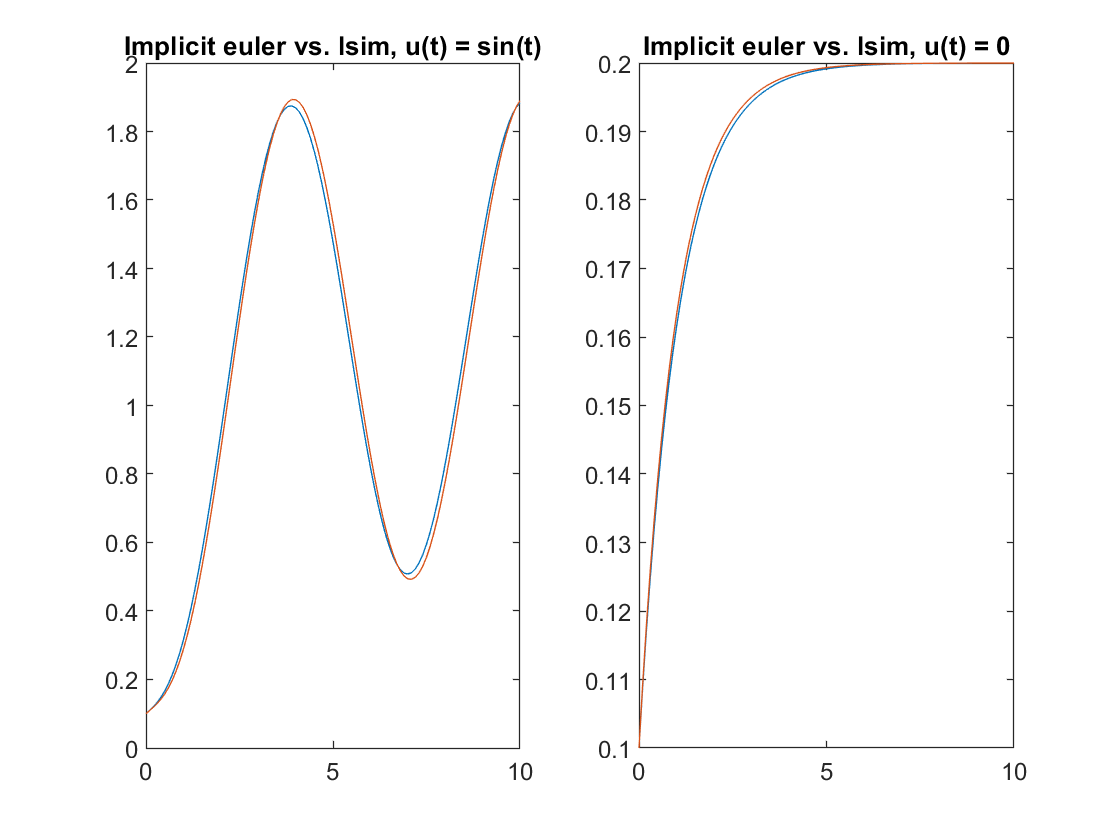


subplot(1,2,2);
[t,y_eulerb_0] = backward_euler(h, time, x0,u2);

plot(t,y_eulerb_0,t,y_lsim_0);
title('Implicit euler vs. lsim, u(t) = 0')

fehler_eilsim_0 = max(abs(y_eulerb_0-y_lsim_0)) % max. fehler impl. euler

fehler_eilsim_0 = 0.0018

## Task 4

Vergleiche zwischen bisherigen Ergebnissen und c2d:

figure(4)
subplot(2,1,1);
sysd = c2d(sys, h);
[y_c2d_sin,~,~] = lsim(sysd, u1, t, x0);
plot(t,y_c2d_sin,t,y_lsim_sin,t,y_eulerf_sin, t, y_eulerb_sin);
title('explicit euler vs. c2d vs. lsim vs. implicit euler');
legend('c2d','lsim','explicit euler', 'implicit euler');
fehler_c2d_sin = max(abs(y_lsim_sin-y_c2d_sin'))

fehler_c2d_sin = 0.0378

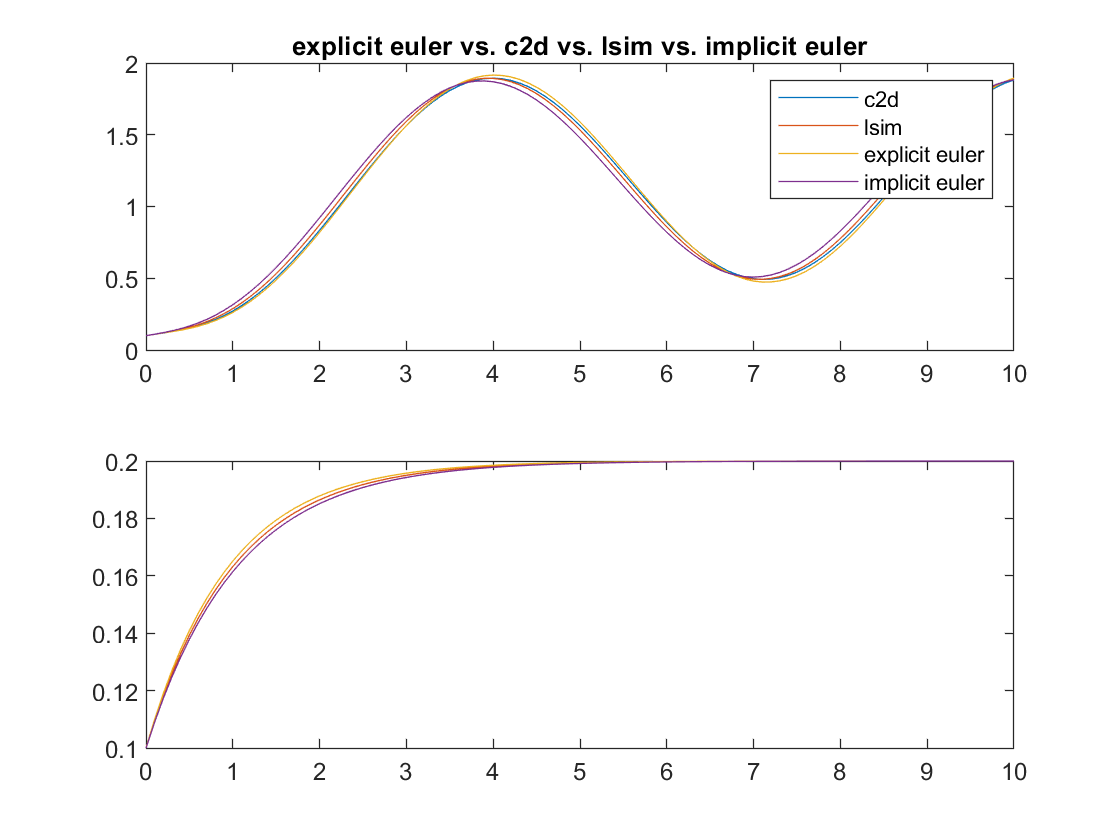


subplot(2,1,2);
[y_c2d_0,~,~] = lsim(sysd, u2, t, x0);
plot(t,y_c2d_0,t,y_lsim_0,t,y_eulerf_0, t, y_eulerb_0);

% title('explicit euler vs. c2d vs. lsim vs. implicit euler');
% legend('c2d','lsim','explicit euler', 'implicit euler');


fehler_c2d_0 = max(abs(y_lsim_0-y_c2d_0'))

fehler_c2d_0 = 0

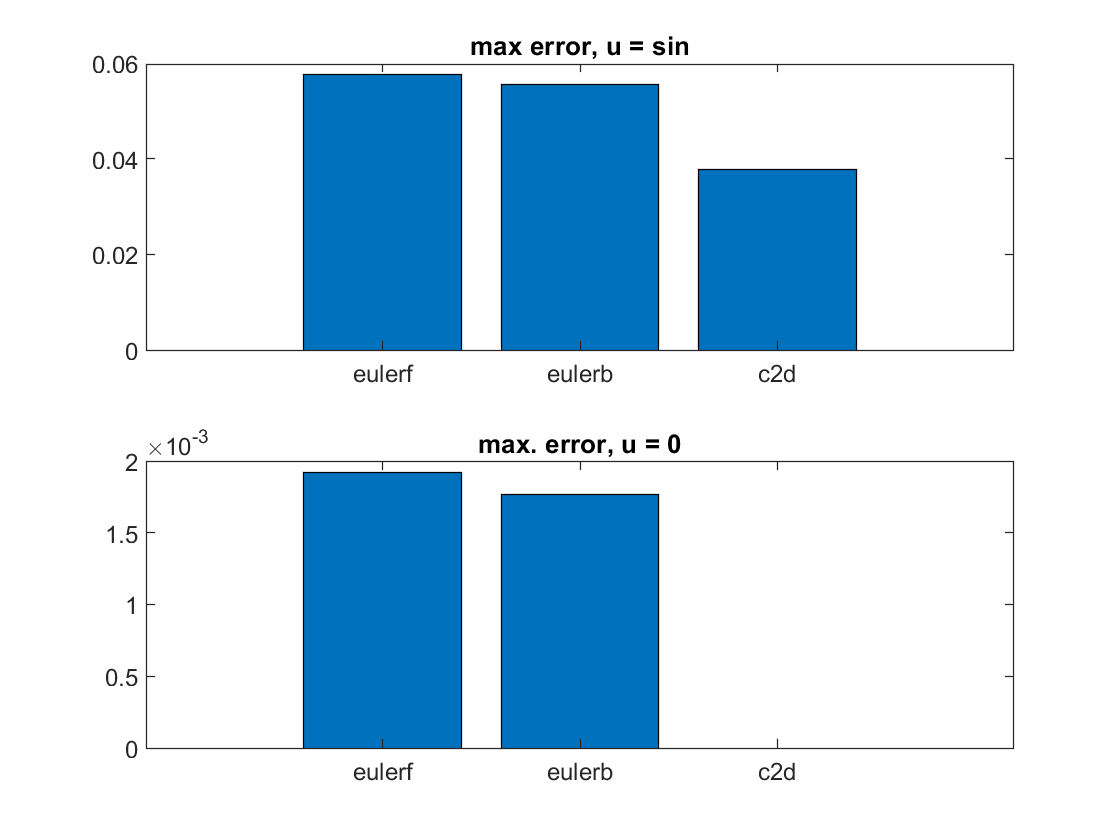


figure(5);
subplot(2,1,1);
bar([fehler_eelsim_sin,fehler_eilsim_sin,fehler_c2d_sin])
set(gca,'xticklabel', ["eulerf","eulerb","c2d"]);
title('max error, u = sin');

subplot(2,1,2);
bar([fehler_eelsim_0,fehler_eilsim_0,fehler_c2d_0]);
set(gca,'xticklabel', ["eulerf","eulerb","c2d"]);
title('max. error, u = 0');

## Appendix

function [t,y] = forward_euler(h,time,x_0,u)
    k_max = int16(time/h)+1;
    assert(length(u) == k_max);
    t = 0:h:time;
    n = size(x_0,1);
    x = zeros(n,length(u));
    
    for i = 0:k_max-1
        if i == 0
            x(:,i+1) = x_0; % matlab indices start at 1
        else
%             x(:,i+1) = x(:,i) + h*([-1 0; 1 0] * x(:,i) + [u(i);0]);
            x(:,i+1) = x(:,i) + h * ([-x(1,i) + u(i); x(1,i)]);
        end
    end
    y = x(2,:);
end
        

function [t,y] = backward_euler(h,time,x_0,u)
    k_max = int16(time/h)+1;
    assert(length(u) == k_max);
    t = 0:h:time;
    n = size(x_0,1);
    x = zeros(n,length(u));
    
    for i = 0:k_max-1
        if i == 0
            x(:,i+1) = x_0; % matlab indices start at 1
        else
%             x(:,i+1) = x(:,i) + h*([-1 0; 1 0] * x(:,i) + [u(i);0]);
%             x(:,i+1) = x(:,i) + h * ([-x(1,i) + u(i); x(1,i)]);
           x(1,i+1) = (x(1,i) + h*u(i+1))/(1+h);
           x(2,i+1) = x(2,i) + h*x(1,i+1);
    end
    y = x(2,:);
    end

end